## 2-D Transformations

Example of 2-D transformations. 

clear all; close all;

## Transformations

Scaling

S = [ 2 0;
      0 3 ]

S =      2     0
     0     3


  
% Shear
G = [ 1.0 0.5; 
      0.0 1.0 ]

G =     1.0000    0.5000
         0    1.0000



% Rotation
theta = pi/8; 
R = [ cos(theta) -sin(theta);
      sin(theta)  cos(theta) ]

R =     0.9239   -0.3827
    0.3827    0.9239


## Original shape

Rectangle given by four vertices

px = [0 4 4 0];   % x-coords
py = [0 0 2 2];   % y-coords  
disp('Input shape')

Input shape


X  = [px;py]        % Matrix containing the 2-D points.

X =      0     4     4     0
     0     0     2     2


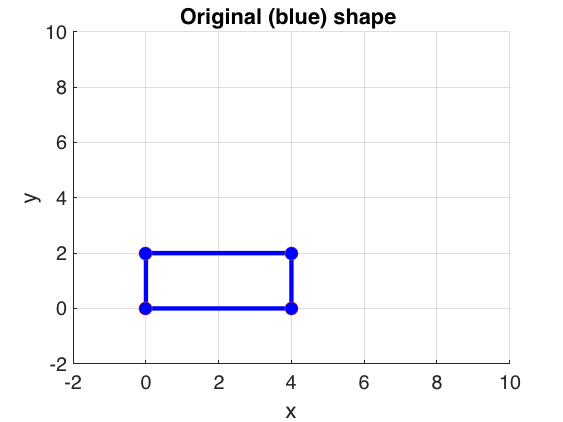

%% Plot shape
figure;
title('Original (blue) shape ');
hold on;
axis([ -2 10 -2 10 ] );
% Repeating the first vertex to close polygon lines
plot([X(1,:) X(1,1)], [X(2,:) X(2,1)], 'b-', 'linewidth',4);
plot([X(1,:) X(1,1)], [X(2,:) X(2,1)], 'o', 'MarkerSize', 12, 'MarkerFaceColor','b')
xlabel('x','FontSize',30);
ylabel('y','FontSize',30);
set(gca, 'fontsize',18);
set(gcf, 'color', 'w' );
grid on;

hold off; 

## Scaling

X_p = S * X

X_p =      0     8     8     0
     0     0     6     6


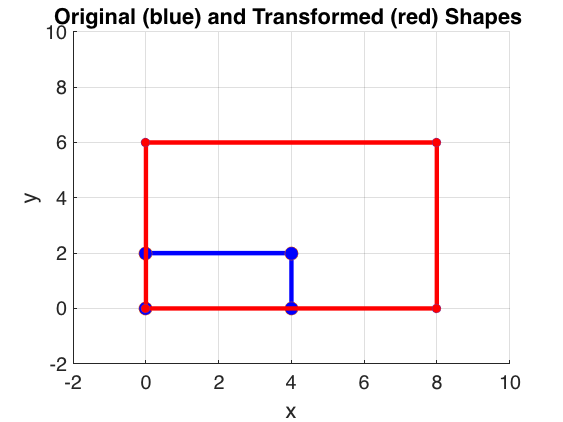


plotShapes(X,X_p);

## Rotation

X_p = R * X 

X_p =          0    3.6955    2.9302   -0.7654
         0    1.5307    3.3785    1.8478


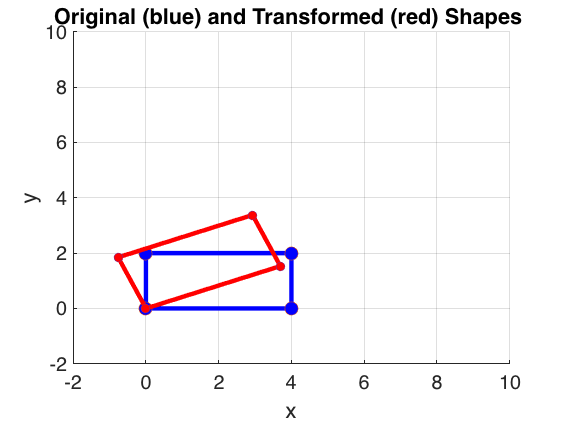


plotShapes(X,X_p);

## Shear

X_p = G * X 

X_p =      0     4     5     1
     0     0     2     2


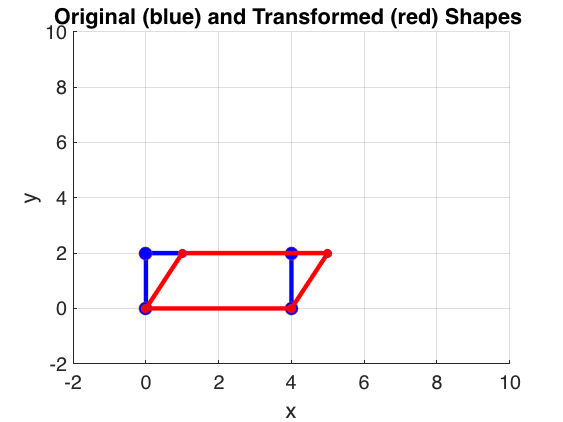


plotShapes(X,X_p);

function plotShapes(X,X_p)
%
%
figure;
title('Original (blue) shape ');
hold on;
axis([ -2 10 -2 10 ] );
% Repeating the first vertex to close polygon lines
plot([X(1,:) X(1,1)], [X(2,:) X(2,1)], 'b-', 'linewidth',4);
plot([X(1,:) X(1,1)], [X(2,:) X(2,1)], 'o', 'MarkerSize', 12, 'MarkerFaceColor','b')
xlabel('x','FontSize',30);
ylabel('y','FontSize',30);
set(gca, 'fontsize',18);
set(gcf, 'color', 'w' );
grid on;

hold off; hold on;
title('Original (blue) and Transformed (red) Shapes ');
% Show the transformed points
plt = plot([X_p(1,:), X_p(1,1)], [X_p(2,:), X_p(2,1)], 'r-', 'linewidth',4);
plot([X_p(1,:), X_p(1,1)], [X_p(2,:), X_p(2,1)], 'o', 'MarkerSize', 8, 'MarkerFaceColor','r');
% Plot transformed shape transparent
plt.Color(4) = 0.5;
grid on;
hold off;
end